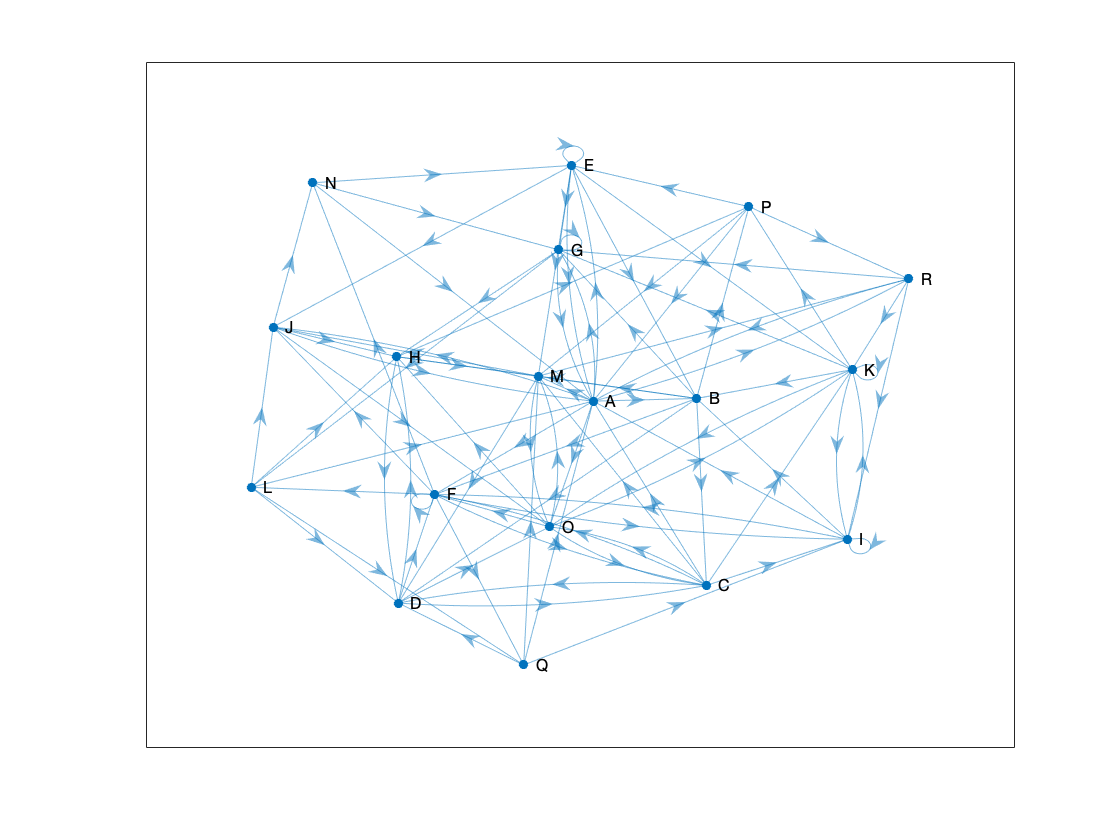

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% SYSTEM PARAMETERS
%% PHYSICAL LEVEL
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Create adjacency matrix .
%%%%%A B C D E F G H I J K L M N O P Q R
A = [0 1 0 0 1 1 1 0 0 1 0 0 1 0 1 0 0 1;%A
     0 0 1 1 0 1 1 1 0 0 0 0 1 0 0 1 0 0;%B
     1 0 0 1 0 1 0 0 1 0 1 0 1 0 1 0 0 0;%C
     0 0 1 0 0 1 0 1 0 0 0 0 0 0 1 0 0 0;%D
     1 1 0 0 1 0 1 0 0 1 1 0 1 0 0 0 0 0;%E
     0 0 1 0 0 1 0 0 1 1 0 1 0 1 0 0 1 0;%F
     1 0 0 0 0 0 1 1 0 0 0 1 0 0 0 0 0 0;%G
     0 0 0 1 0 0 0 0 0 0 0 0 1 0 0 1 0 0;%H
     1 1 0 0 0 1 0 0 1 0 1 0 0 0 0 0 0 0;%I
     1 0 0 0 0 0 0 1 0 0 0 0 0 1 1 0 0 0;%J
     0 1 0 0 0 0 1 0 1 0 1 0 0 0 1 1 0 0;%K
     1 0 0 1 0 0 0 1 0 1 0 0 0 0 0 0 1 0;%L
     0 0 0 1 0 0 0 0 0 1 0 0 0 0 1 0 0 1;%M
     1 0 0 0 1 0 1 0 0 0 0 0 0 0 0 0 0 0;%N
     0 0 1 0 0 1 0 1 0 0 1 0 1 0 0 0 0 0;%O
     1 0 0 0 1 0 0 0 0 0 0 0 1 0 0 0 0 1;%P
     1 0 0 1 0 0 0 0 1 0 0 0 1 0 0 0 0 0;%Q
     1 0 0 0 0 0 1 0 1 0 1 0 0 0 0 0 0 0];%R

%ID dei nodi 
nodes = {'A' 'B' 'C' 'D' 'E' 'F' 'G' 'H' 'I' 'J' 'K' 'L' 'M' 'N' 'O' 'P' 'Q' 'R'};
%Batteria iniziale
num_nodes = numel(nodes);%numero di nodi
battery = zeros(size(nodes)); %la inizializzo per ottimizzare, evito warning

for i=1:num_nodes
    battery(i) = 100;  %inizialmente il valore di tutte le batterie è 10
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%% VARIABILI 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
B_max = 10;     %valore massimo della batteria
B_critical = 2;     %valore critico che richiede la ricarica
B_min = 0;      %valore minimo della batteria
root = 1;   %prendo il nodo A come root
root_battery = battery(1);
Cost_Rx = 0.6;    %costo ricezione
Cost_Tx = 0.5;  %costo trasmissione
P_Rx = 0.3;     %premio ricezione 
Time = 0;       %tempo trascorso,colpi di clock
Energy = 180.0;   %somma di tutti i valori delle batterie

% Create undirected graph object
G = digraph(A,nodes);
plot(G);

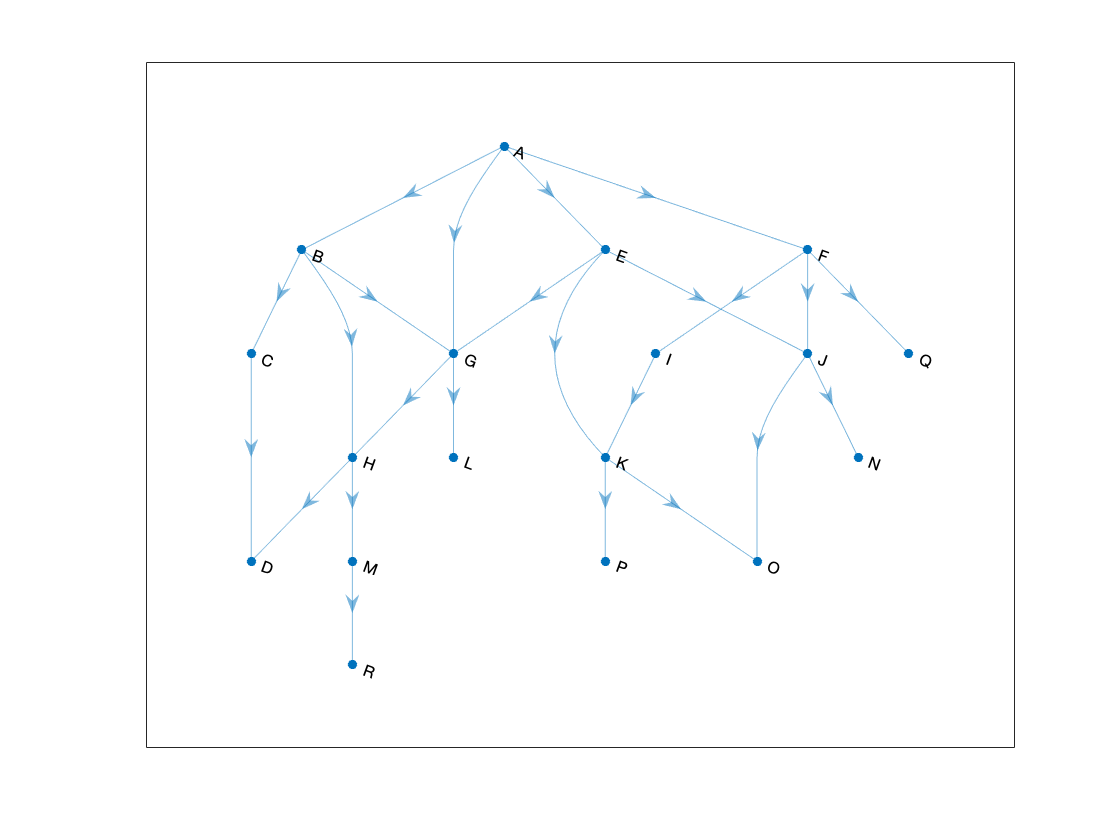


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% NETWORK LEVEL
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%vado a tagliare le comunicazioni nella matrice di adiacenza

%%%%%A B C D E F G H I J K L M N O P Q R
B = [0 1 0 0 1 1 1 0 0 0 0 0 0 0 0 0 0 0;%A
     0 0 1 0 0 0 1 1 0 0 0 0 0 0 0 0 0 0;%B
     0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%C
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%D
     0 0 0 0 0 0 1 0 0 1 1 0 0 0 0 0 0 0;%E
     0 0 0 0 0 0 0 0 1 1 0 0 0 0 0 0 1 0;%F
     0 0 0 0 0 0 0 1 0 0 0 1 0 0 0 0 0 0;%G
     0 0 0 1 0 0 0 0 0 0 0 0 1 0 0 0 0 0;%H
     0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 0 0 0;%I
     0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 0 0 0;%J
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 0 0;%K
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%L
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1;%M
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%N
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%O
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%P
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0;%Q
     0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];%R


% Create undirected graph object
H = digraph(B,nodes);
% Plot
plot(H);

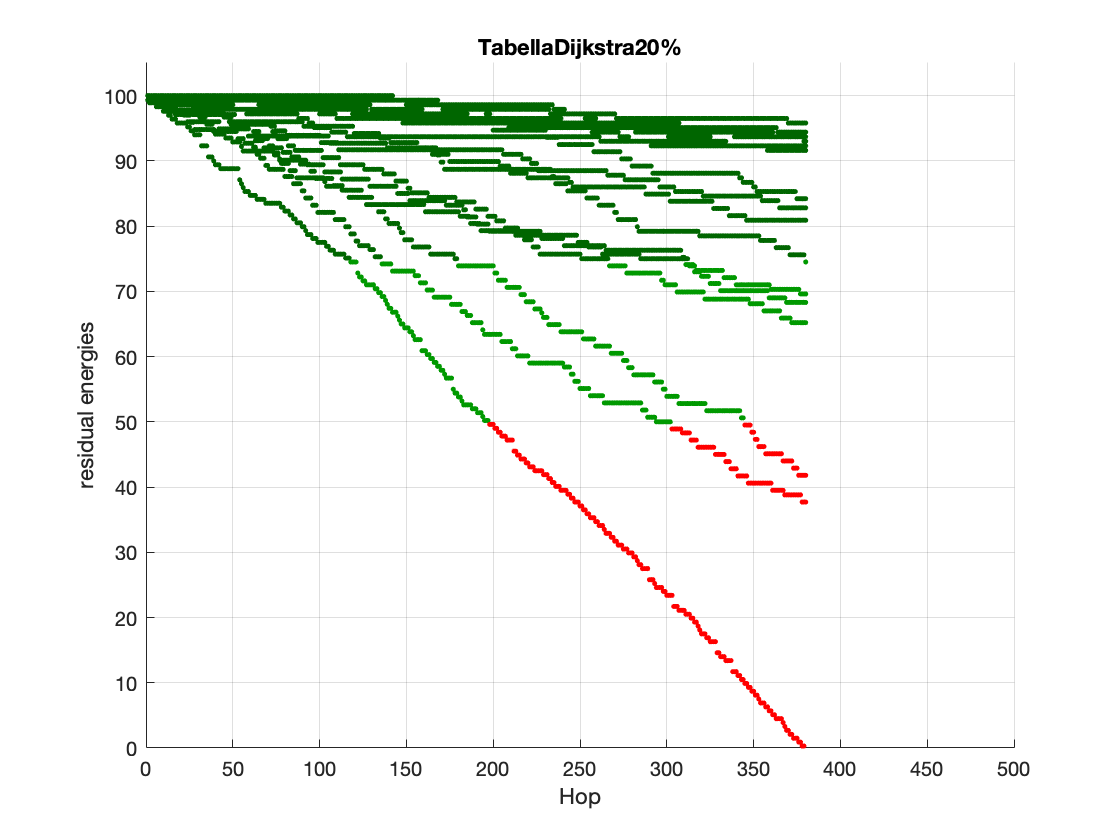

P = zeros(18,18); %inizializzo la matrice dei pesi
for i = 1: num_nodes
   P(i,:) = B(i,:) * 1/battery(i); %matrice dei pesi
end
disponibile = true;
passaggio = 0.1;
token = zeros(num_nodes,1);
sensing = 0.2;
hop = 0;
i = 0;
for nodo = 1 : num_nodes
    if nodo == 1 
        i = i+1;
        j = 1;
        routes(i,j) = {nodo};
    end
    if nodo ~= 1
        padre = 0;
        i = i+1;
        j = 1;
        routes(i,j) = {nodo};
        j = j+1;
        while(padre(1,1) ~= 1)
            padre = find(any(B(:,nodo)==1,2));%il padre sarà la colonna dove è uguale a 1
            select = randi([1,numel(padre)],1,1);
            padre(select,1);
            routes(i,j) = {padre(select,1)};
            nodo = padre(select,1);           %mi serve per il padre del padre
            j= j+1;
%             padre = find(any(B(:,nodo)==1,2));%il padre sarà la colonna dove è uguale a 1
%             padre(1,1);
%             routes(i,j) = {padre(1,1)};
%             nodo = padre(1,1);           %mi serve per il padre del padre
%             j= j+1;
        end  
    end
end

percorso = ~cellfun('isempty',routes);
length = sum(percorso,2); %questa è la lunghezza 
dijkstra = 0; %contatore che mi dice quante volte ricalcolo il cammino
figure;
hold on;
grid on;
index = 0;
sensingCounter = 0;
while disponibile    
   select = randi ([1,num_nodes],1,1);
   sensingCounter = sensingCounter +1;
   ricalcola = randi([1,10]);
   if(ricalcola == 5 || ricalcola == 3) %20% delle volte lo ricalcolo
        [costo,route] = Dijkstra(B,1,select);
        for i = 1 : size(route,2)
            [routes{select,i}] = route(i);
             dijkstra = dijkstra+1;
        end
   end
   for i = 1 : length(select)-1
       if disponibile ~= false 
           index = index +1;
            %la sorgente
            if i == 1
                battery([routes{select,i}]) = battery([routes{select,i}])-Cost_Tx-sensing;%deve solo trasmettere poichè  è la sorgente
                token([routes{select,i}]) = token([routes{select,i}])+1;
            end
       
            %% il cammino tra la sorgente e la destinazione
            if i~=1 && i ~= length(select)% negli altri casi
                battery([routes{select,i}]) = battery([routes{select,i}])-Cost_Rx-Cost_Tx; 
                token([routes{select,i}]) = token([routes{select,i}])+1;
            end
       
            %% destinazione, sempre la radice
            if i+1 == length(select)
                battery([routes{select,i+1}]) = battery([routes{select,i+1}])-Cost_Rx; %deve ricevere poichè è la destinazione, cioè la radice
                token([routes{select,i+1}]) = token([routes{select,i+1}])+1;
            end
            %calcolo jain index
            Energy = 0;
            for t = 2: num_nodes
                Energy = Energy+battery(t);
            end
            
            battery_opt = Energy/num_nodes; %la situazione ottimale sarebbe con tutti la batteria media
            battery_num = 0;
            for k = 2:num_nodes
                  battery_num = battery_num+ battery(k)/battery_opt;
            end
            
            jain_num = battery_num^2;
            
            battery_den = 0;
             
            for s = 2 : num_nodes
                 battery_den = battery_den + (battery(s)/battery_opt)^2;
            end
            jain_den = (num_nodes-1)*battery_den;
            jain_index(index) = jain_num/jain_den;
            %fine calcolo jain index
            hop = hop+1;
            for j = 1: num_nodes
                if battery(j)>= 75
                    plot(hop,battery(j),'.','LineWidth',0.5,"Color",'#006600'); 
                end
                if battery(j)>= 50 && battery(j)< 75
                    plot(hop,battery(j),'.','LineWidth',0.5,"Color",'#009900');
                end
                if battery (j) < 50
                    plot(hop,battery(j),'.','LineWidth',0.5,"Color",'r'); 
                end
                if battery(j) <= 0
                    disponibile = false;
                end
            end
           
        end
   end
end
 axis([0 500 0 105]);
 xlabel('Hop');
 ylabel('residual energies');
 title('TabellaDijkstra20%');
 hold off;

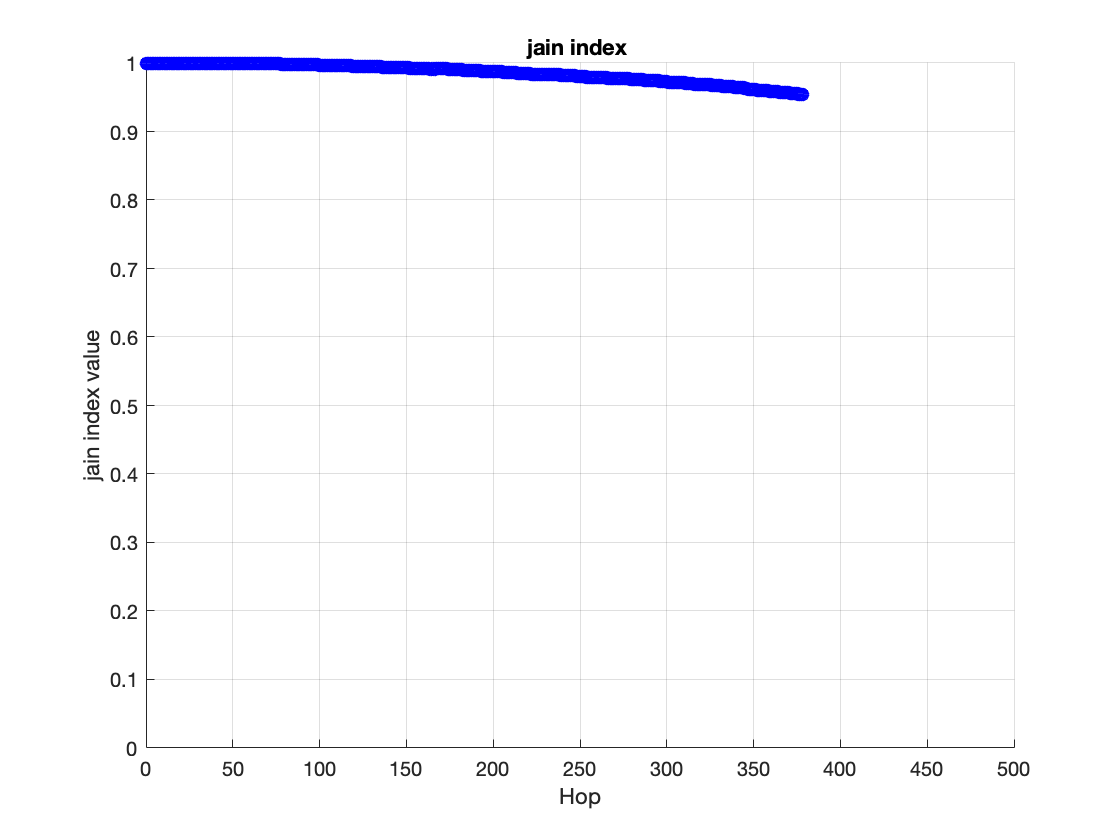

hop = 0;
h(2) = figure;
hold on;
grid on;
for index = 2 : numel(jain_index)
    plot(hop,jain_index(index),'o','Color','#0000ff');
    hop = hop +1;
end
axis([0 500 0 1]);
xlabel('Hop');
ylabel('jain index value');
title('jain index ');
hold off;
 
savefig(h(2),'JainIndex2finale2.fig');

sensingCounter

sensingCounter = 175